clear
clc

## Problem 2. Lorenz Equation

a. Orbit solution

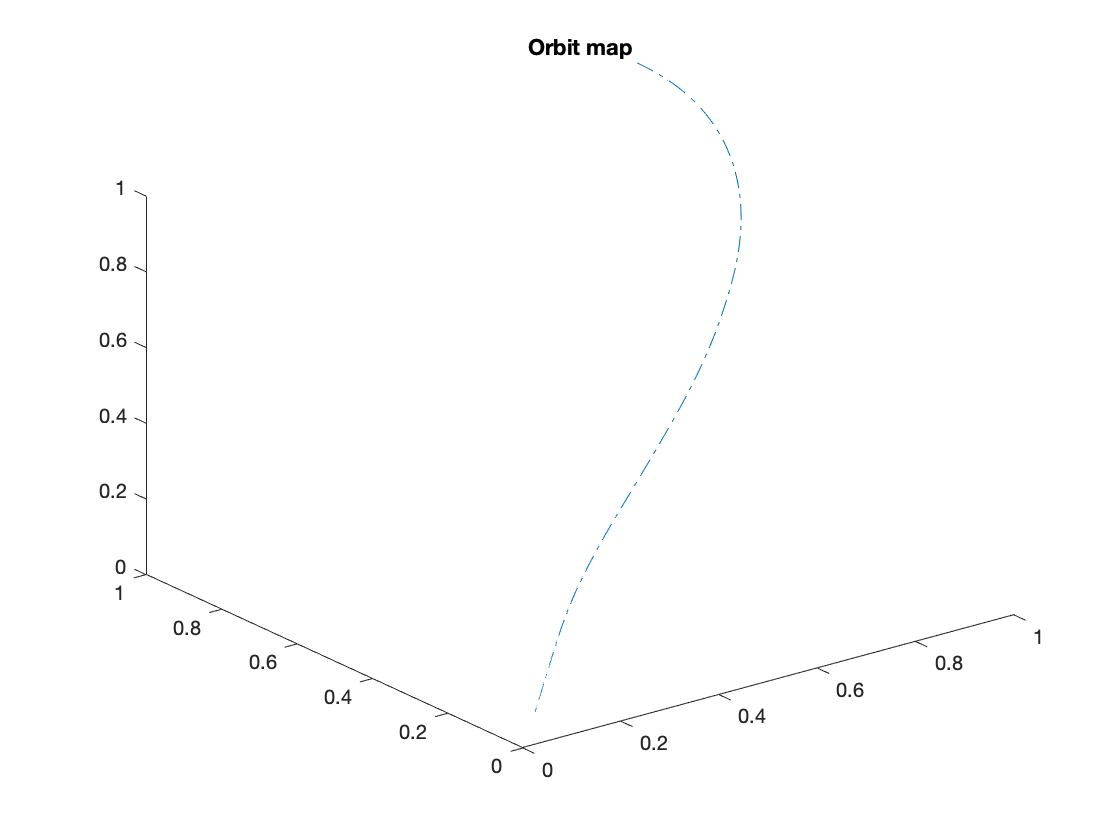

sigma = 1;
beta = 1;
rho = 1;
x0 = 1;
y0 = 1;
z0 = 1;
tspan = [0:0.01:100];
yy0 =[x0,y0,z0];
[t,y] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0);
figure
plot3(y(:,1),y(:,2),y(:,3),'-.')
title('Orbit map')

b. Earth's atmosphere

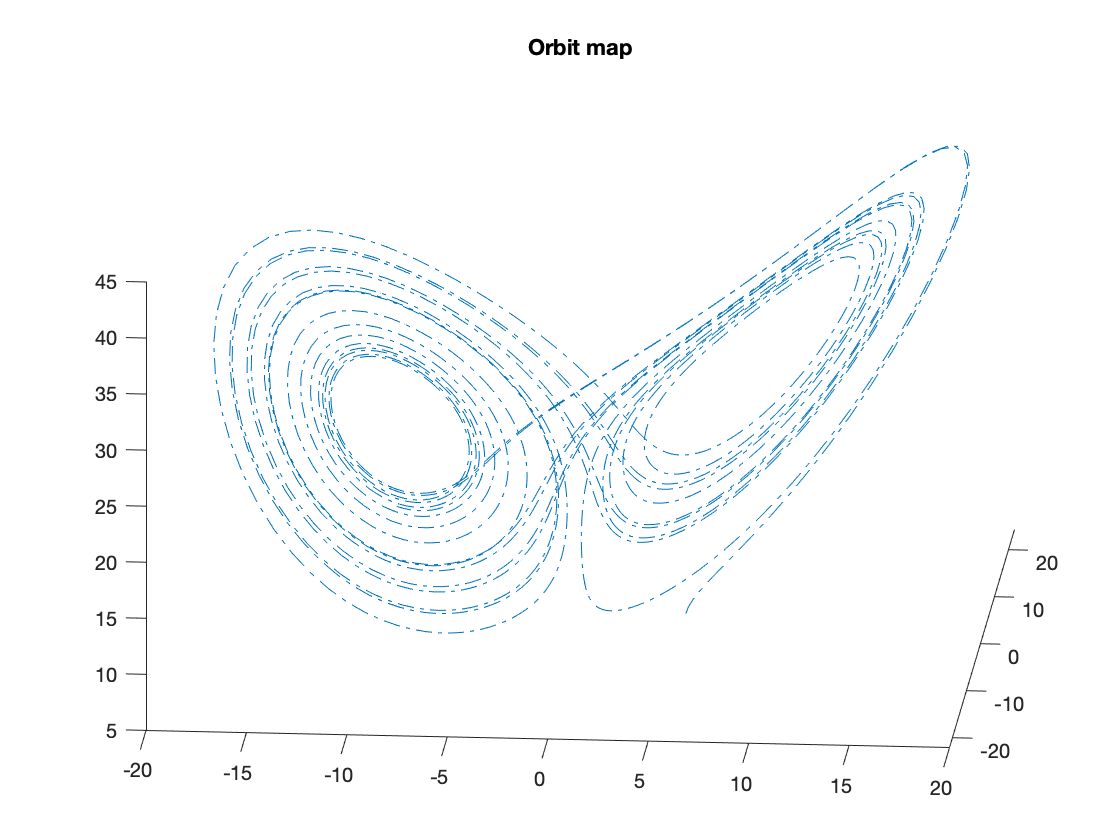

sigma = 10;
beta = 8/3;
rho = 28;
x0 = 5;
y0 = 5;
z0 = 5;
tspan = [0:0.01:20];
yy0 =[x0,y0,z0];
[t,y] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0);
figure
plot3(y(:,1),y(:,2),y(:,3),'-.')
title('Orbit map')

view([4.6 26.1])

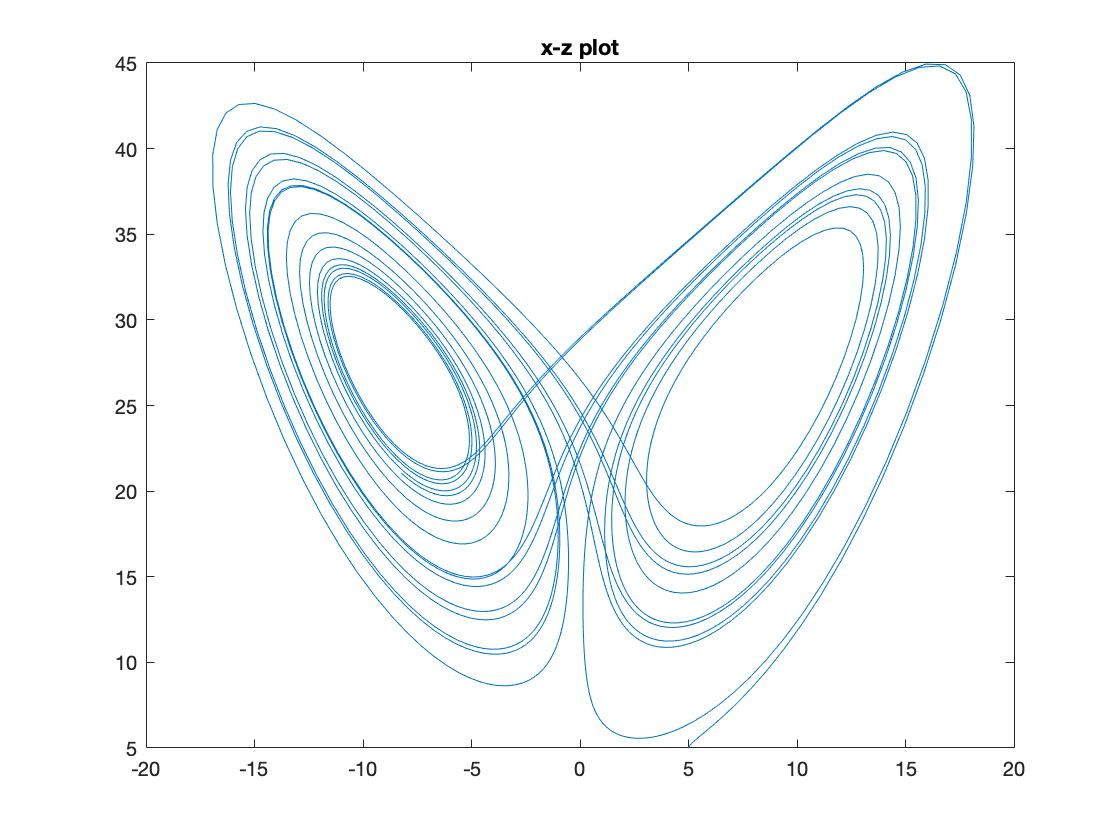

figure
plot(y(:,1),y(:,3))
title('x-z plot')

c. Plot x,y,z, vs time using subplot

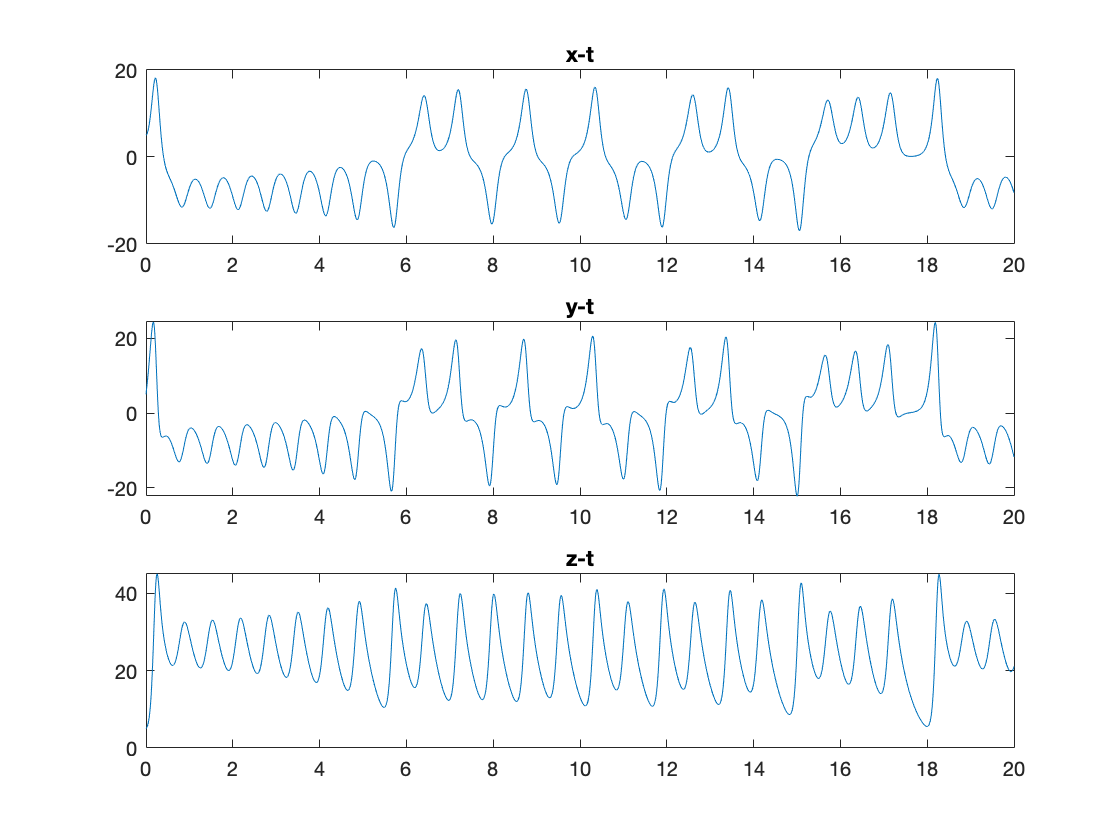

figure
subplot(3,1,1);
plot(t,y(:,1))
title('x-t')

subplot(3,1,2);
plot(t,y(:,2))
title('y-t')

subplot(3,1,3);
plot(t,y(:,3))
title('z-t')

d. Add perturbation

tspan = [0:0.01:50];
[t,y1] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0);
x0 = x0+10^(-6)

x0 = 5.0000

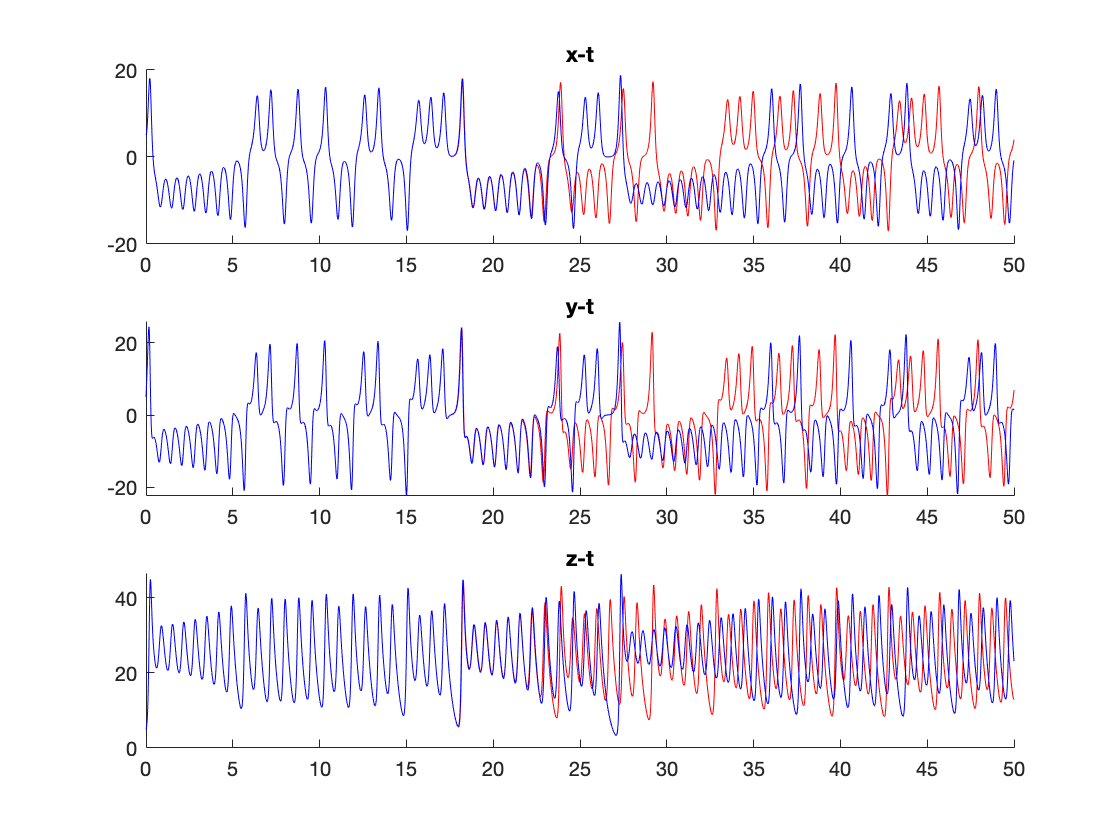

yy0 =[x0,y0,z0];
[t,y2] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0);

figure
subplot(3,1,1);
hold on
plot(t,y1(:,1),'r')
plot(t,y2(:,1),'b')
hold off
title('x-t')

subplot(3,1,2);
hold on
plot(t,y1(:,2),'r')
plot(t,y2(:,2),'b')
hold off
title('y-t')

subplot(3,1,3);
hold on
plot(t,y1(:,3),'r')
plot(t,y2(:,3),'b')
hold off
title('z-t')

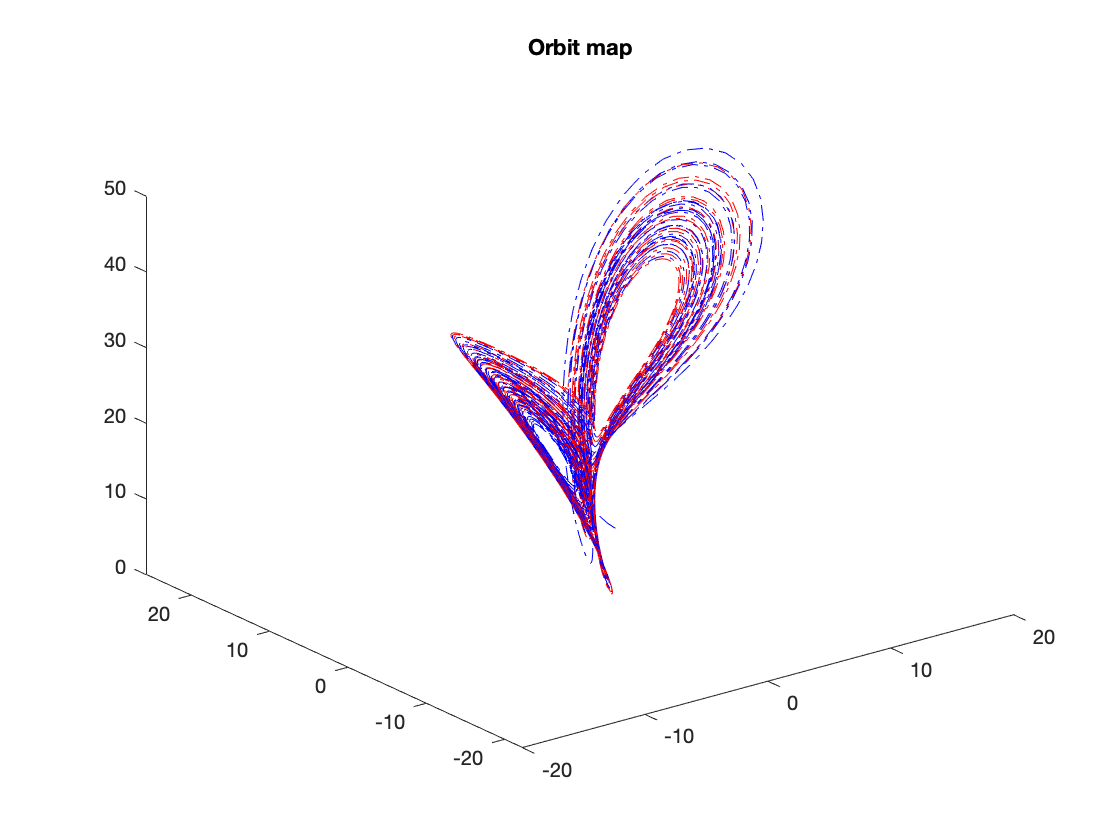


figure
plot3(y1(:,1),y1(:,2),y1(:,3),'-.r')
hold on
plot3(y2(:,1),y2(:,2),y2(:,3),'-.b')
hold off
title('Orbit map')

'diverge at around 22'

ans = 'diverge at around 22'

e. find rho

tspan = [0:0.01:50];
for i = 500:1000
    rho = i/10;
    x0 = 5;
    yy0 =[x0,y0,z0];
    [t,y1] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0);
    x0 = x0+10^(-6);
    yy0 =[x0,y0,z0];
    [t,y2] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0);
    if max(y1-y2)<0.01
        rho
        break
    end
end

rho = 92.9000

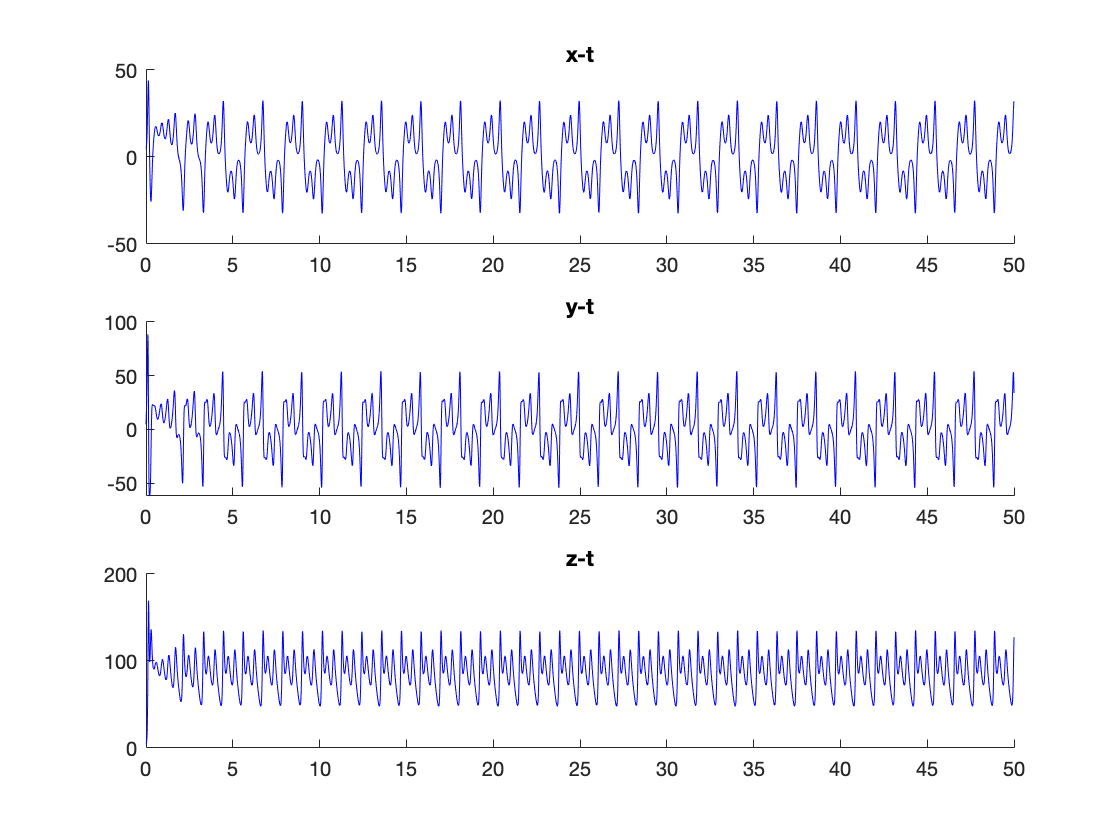



figure
subplot(3,1,1);
hold on
plot(t,y1(:,1),'r')
plot(t,y2(:,1),'b')
hold off
title('x-t')

subplot(3,1,2);
hold on
plot(t,y1(:,2),'r')
plot(t,y2(:,2),'b')
hold off
title('y-t')

subplot(3,1,3);
hold on
plot(t,y1(:,3),'r')
plot(t,y2(:,3),'b')
hold off
title('z-t')

f. 

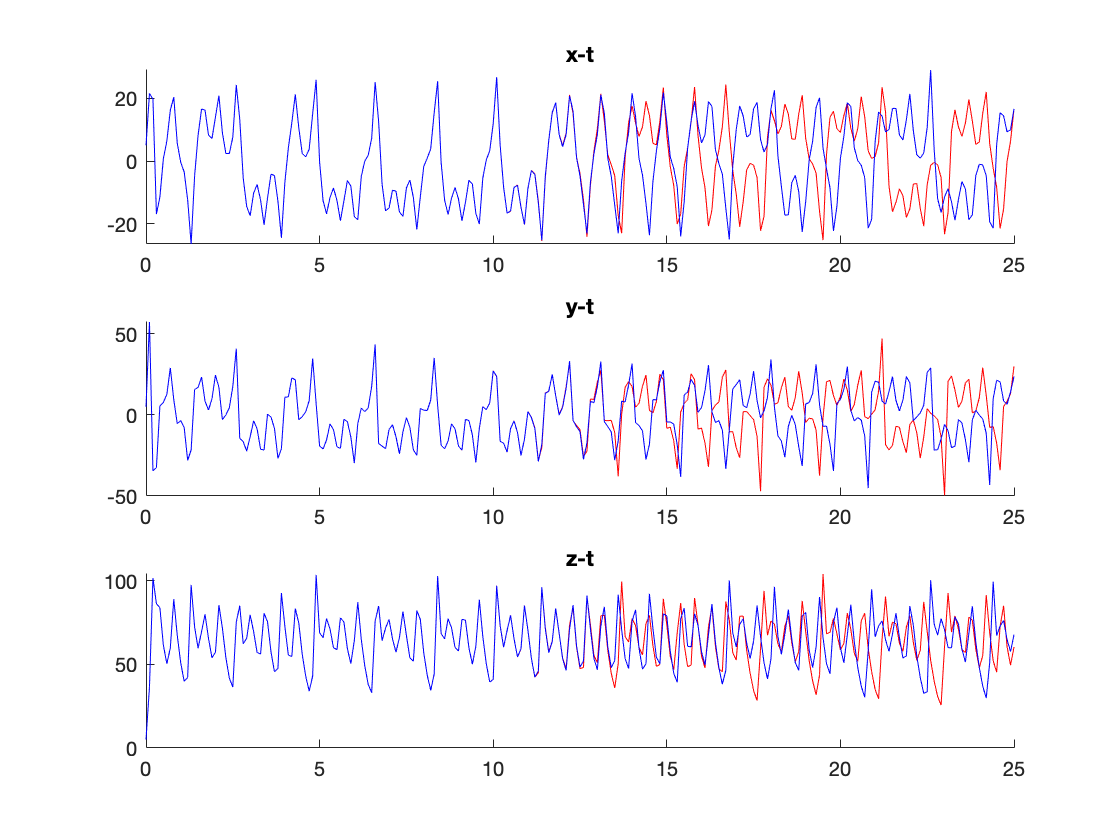

rho = 70;

tspan = [0:0.1:25];
x0 = 5;
yy0 =[x0,y0,z0];
opts1 = odeset('MaxStep',2.5);
[t1,y1] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0,opts1);
x0 = x0+10^(-6);
yy0 =[x0,y0,z0];
[t1,y2] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0,opts1);

opts2 = odeset('MaxStep',0.0025);
x0 = 5;
yy0 =[x0,y0,z0];
[t2,y3] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0,opts2);
x0 = x0+10^(-6);
yy0 =[x0,y0,z0];
[t2,y4] = ode45(@(t,y) odefun(t,y,sigma,rho,beta),tspan,yy0,opts2);


figure
subplot(3,1,1);
hold on
plot(t1,y1(:,1),'r')
plot(t1,y2(:,1),'b')
hold off
title('x-t')

subplot(3,1,2);
hold on
plot(t1,y1(:,2),'r')
plot(t1,y2(:,2),'b')
hold off
title('y-t')

subplot(3,1,3);
hold on
plot(t1,y1(:,3),'r')
plot(t1,y2(:,3),'b')
hold off
title('z-t')

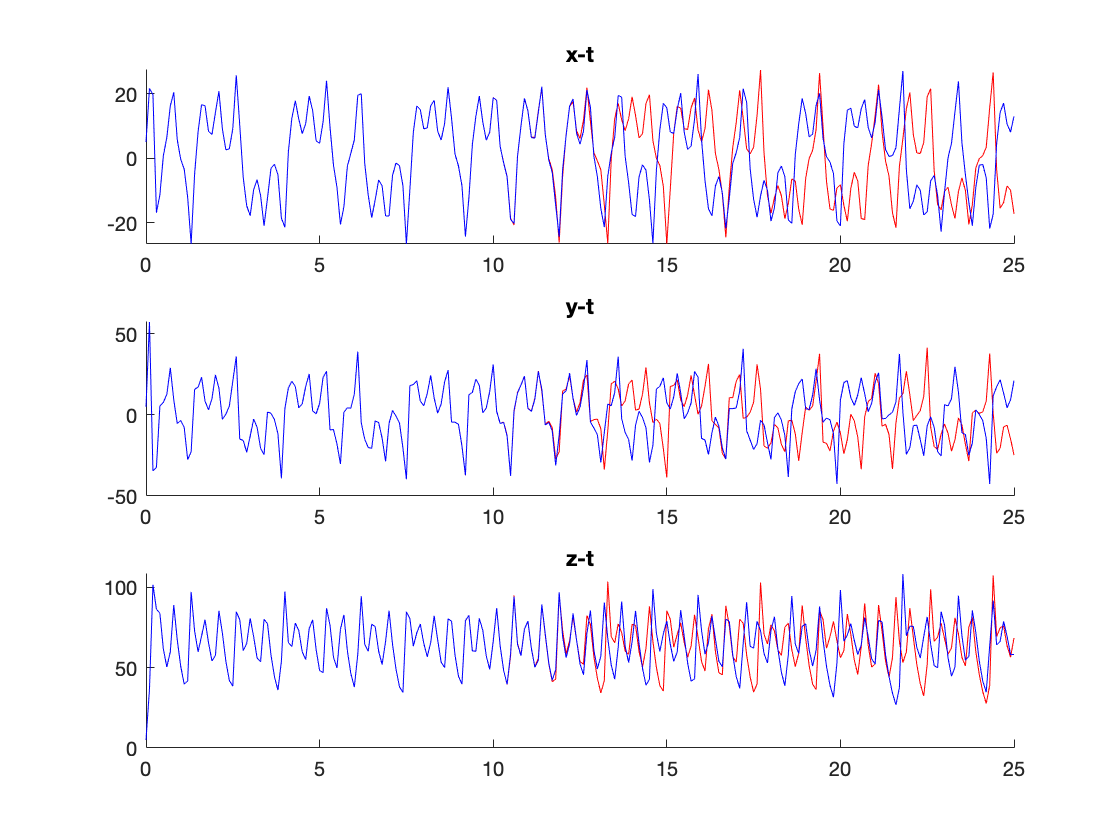



figure
subplot(3,1,1);
hold on
plot(t2,y3(:,1),'r')
plot(t2,y4(:,1),'b')
hold off
title('x-t')

subplot(3,1,2);
hold on
plot(t2,y3(:,2),'r')
plot(t2,y4(:,2),'b')
hold off
title('y-t')

subplot(3,1,3);
hold on
plot(t2,y3(:,3),'r')
plot(t2,y4(:,3),'b')
hold off
title('z-t')


'not relavent'

ans = 'not relavent'

## Lorentz Function definition [x=y(1),y=y(2),z=y(3)]

function dydt = odefun(t,y,sigma,rho,beta)
dydt = zeros(3,1);
dydt(1) = sigma * (y(2)-y(1));
dydt(2) = y(1)*(rho-y(3))-y(2);
dydt(3) = y(1)* y(2)- beta*y(3);
end
